# **De datos sin procesar a información compartible**

- **Introduction to MATLAB** session

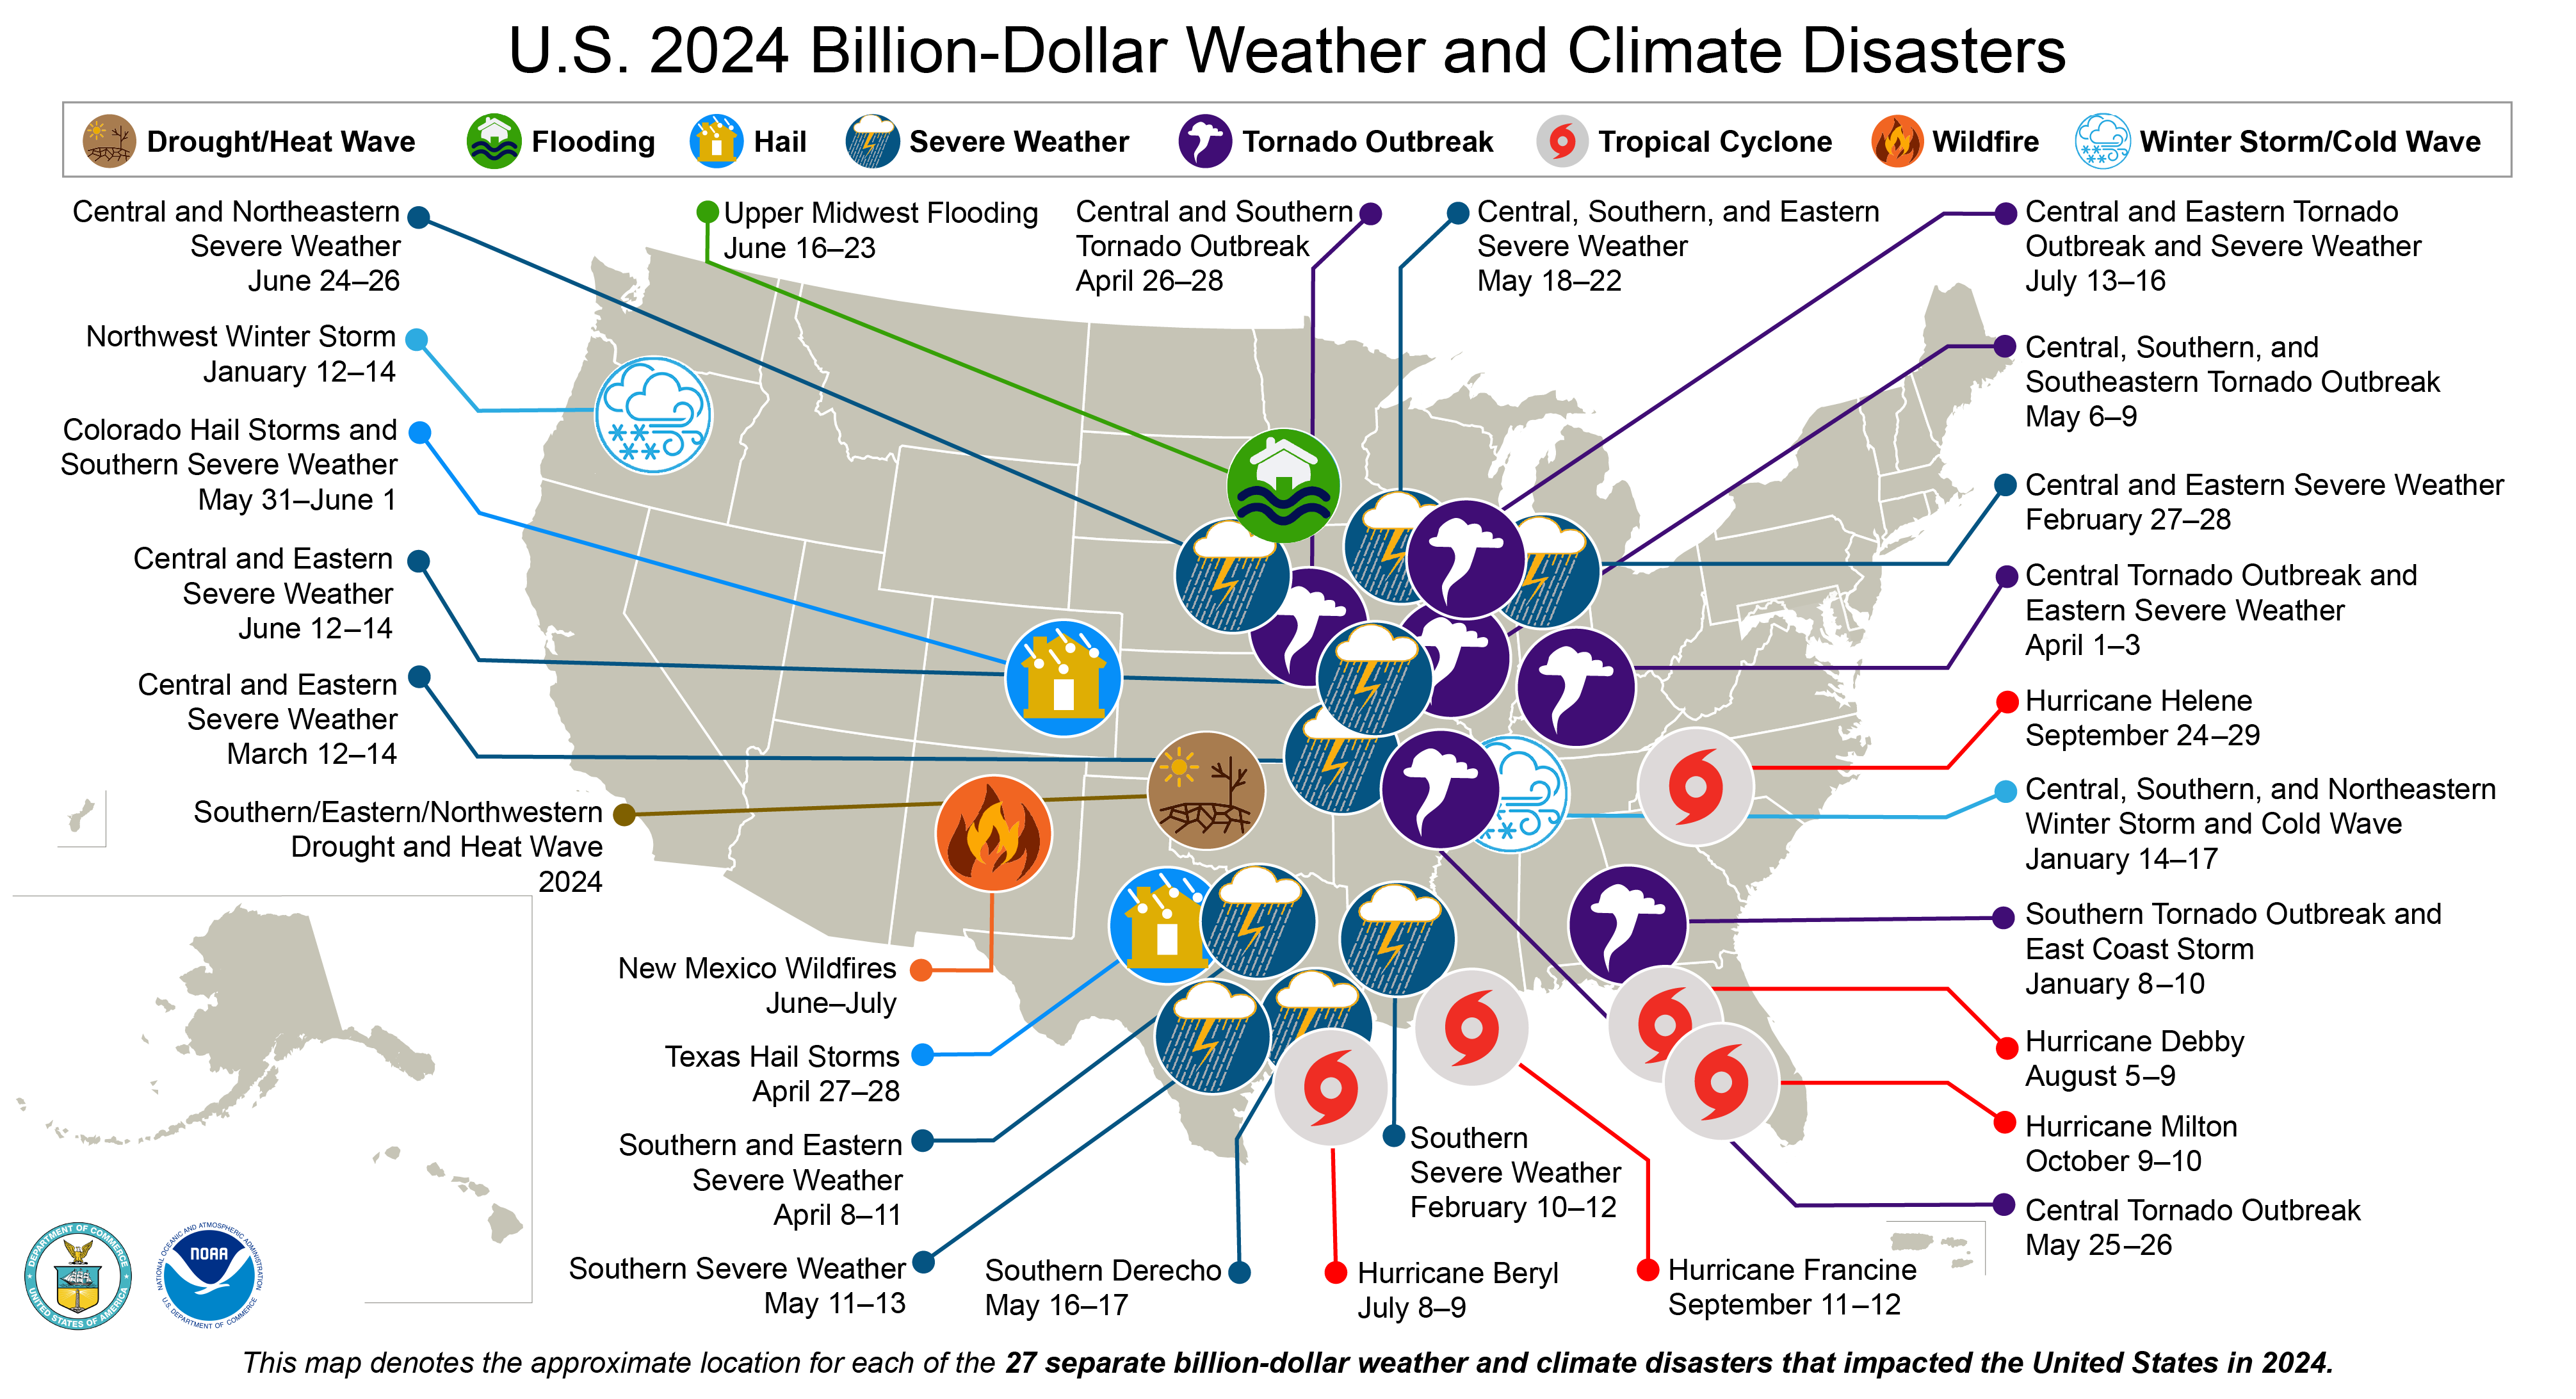

[https://www.climate.gov/news-features/blogs/beyond-data/2023-historic-year-us-billion-dollar-weather-and-climate-disasters](https://www.climate.gov/news-features/blogs/beyond-data/2023-historic-year-us-billion-dollar-weather-and-climate-disasters) 

## 1) Access and Review the Data 

*The storm event data files are freely available from National Oceanic and Atmospheric Administration (NOAA): *[*https://www.ncei.noaa.gov/pub/data/swdi/stormevents/csvfiles/*](https://www.ncei.noaa.gov/pub/data/swdi/stormevents/csvfiles/) 

**For example:** StormEvents_details_d2024_c20230120.csv

writetable(myData,'myData.xls') table to xls

## **2)** Import the Data

[https://www.mathworks.com/help/matlab/import_export/import-data-interactively.html](https://www.mathworks.com/help/releases/R2020a/matlab/import_export/import-data-interactively.html)

myData = importfile('allData\StormEvents_d2021.csv');

## 3) Visualize and Explore the Data

**What Weather Related Financial Costs are Reported?**

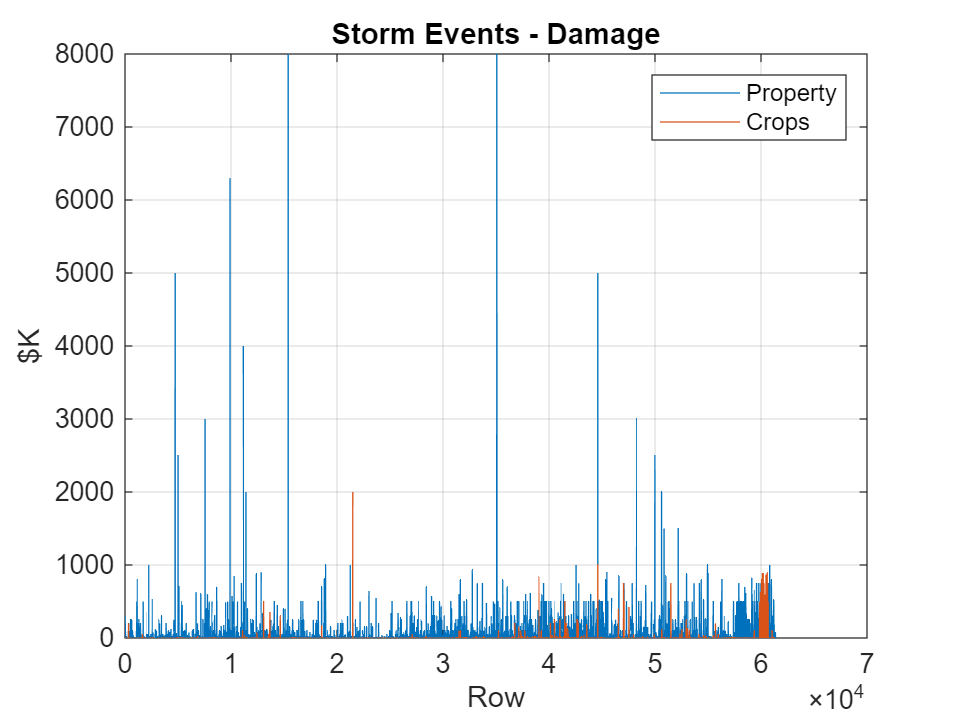

plot(myData.DAMAGE_PROPERTY,'DisplayName','Property');
hold on;
plot(myData.DAMAGE_CROPS,'DisplayName','Crops');
hold off;
legend('show');
ylabel('$K');
xlabel('Row');
grid("on")
title('Storm Events - Damage');

**Observations:**

- More records reporting significant property damage than crop damage

- Fewer records have property damages > $500K

#### **What are the Most Frequent Weather Event Types?**

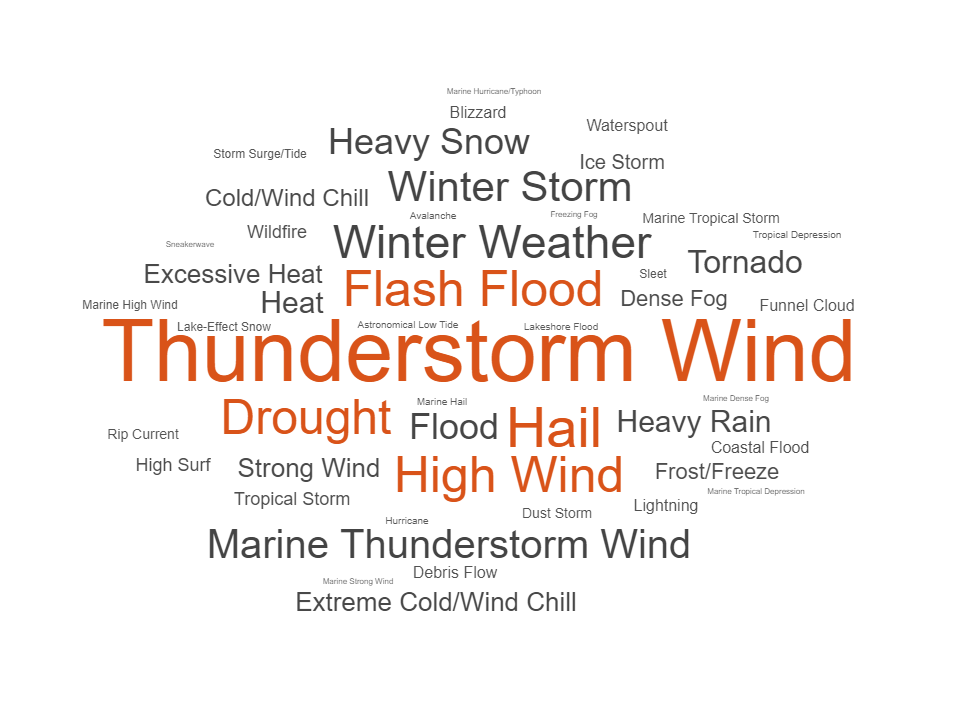

wordcloud(myData.EVENT_TYPE);

#### **When are the most events taken place?**

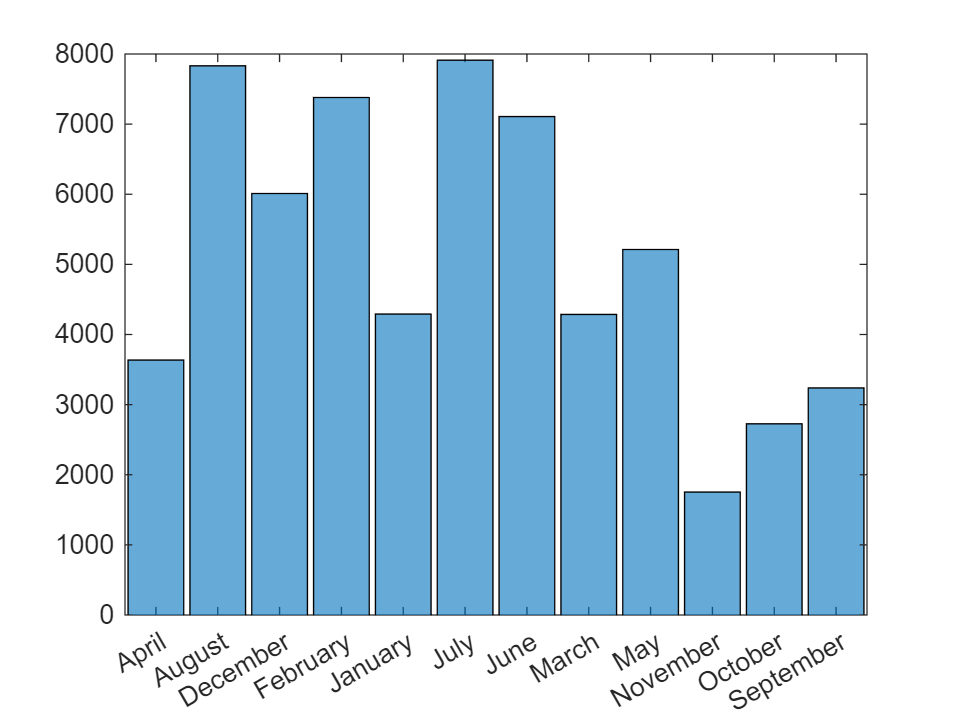

histogram(myData.MONTH_NAME)

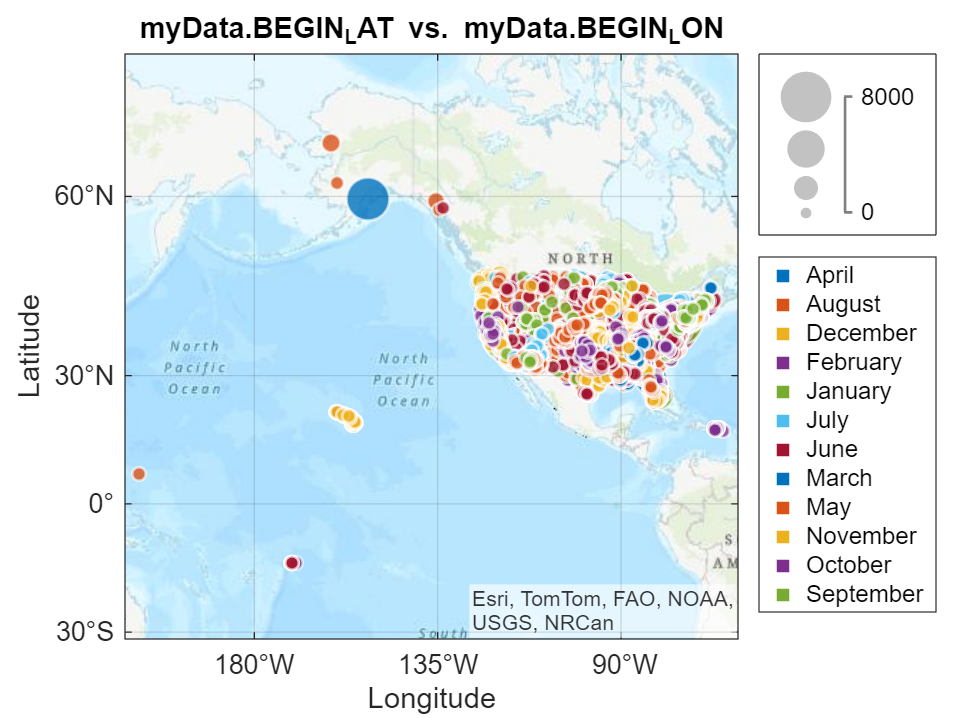

% Create geobubble of selected data
gb = geobubble(myData.BEGIN_LAT,myData.BEGIN_LON,myData.DAMAGE_PROPERTY,myData.MONTH_NAME,"Basemap","topographic");

% Add title
title("myData.BEGIN_LAT vs. myData.BEGIN_LON")

## 4) Determine Amount of Data to be Used for Analysis 

**Goal: Identify Locations Reporting the Higher Property Damages**

[https://www.mathworks.com/help/matlab/ref/findlocalextrema.html](https://www.mathworks.com/help/matlab/ref/findlocalextrema.html)

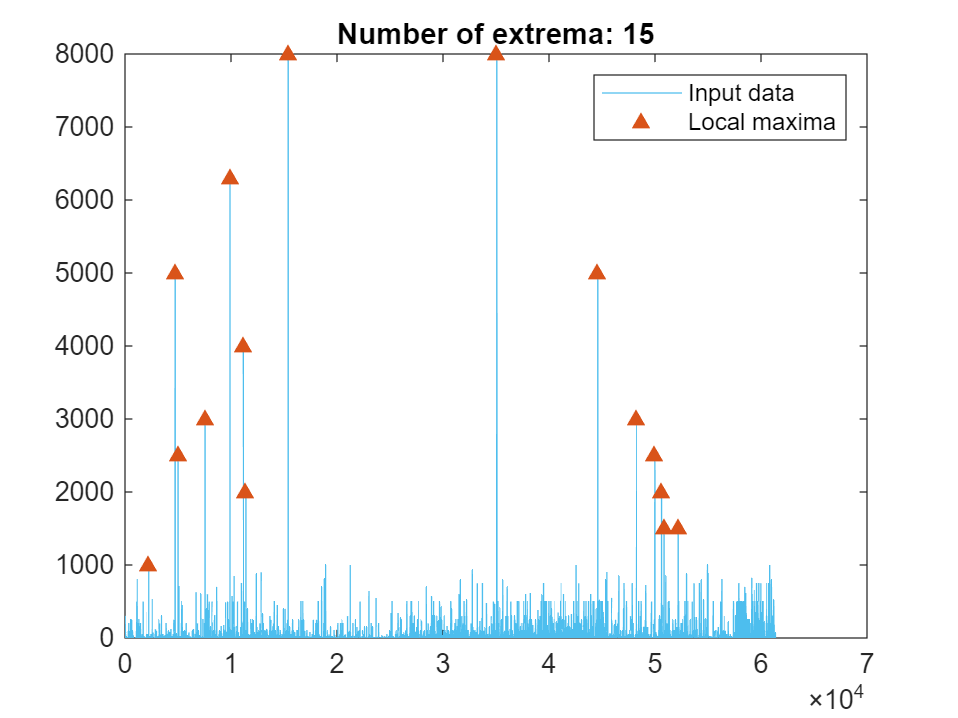

% Find local maxima
maxIndices = islocalmax(myData.DAMAGE_PROPERTY,"MinProminence",1000, ...
    "MaxNumExtrema",15);

% Display results
figure
plot(myData.DAMAGE_PROPERTY,"SeriesIndex",6,"DisplayName","Input data")
hold on

% Plot local maxima
scatter(find(maxIndices),myData.DAMAGE_PROPERTY(maxIndices),"^","filled", ...
    "SeriesIndex",2,"DisplayName","Local maxima")
title("Number of extrema: " + nnz(maxIndices))
hold off
legend

## **Subset of New Data to Report Maximum Damage Areas**

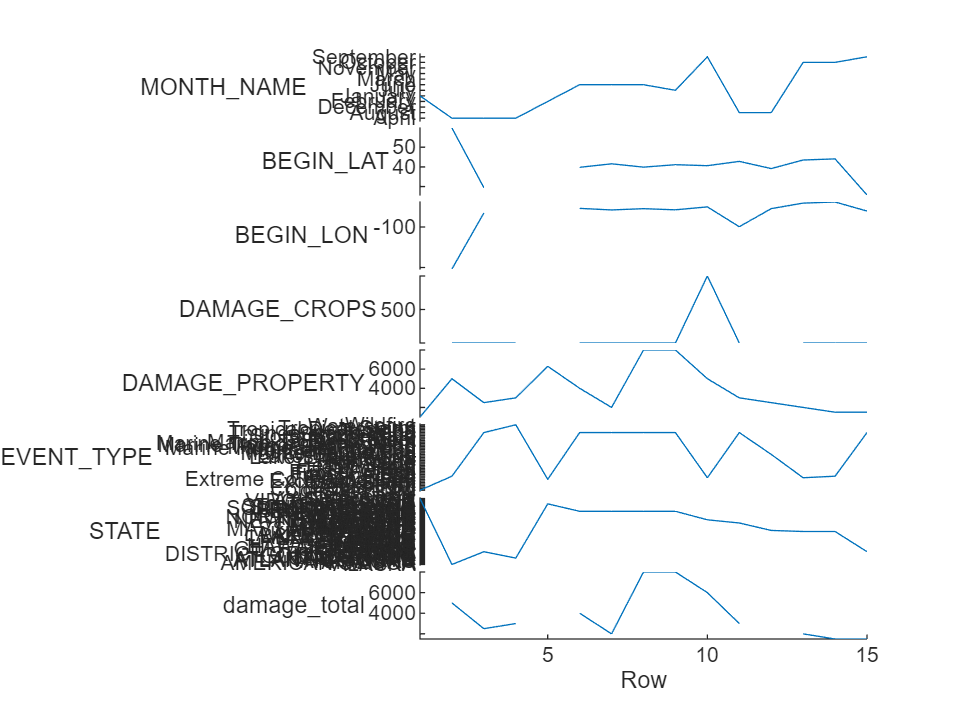

costlyStormEvents = myData(maxIndices,["MONTH_NAME","BEGIN_LAT","BEGIN_LON","DAMAGE_CROPS","DAMAGE_PROPERTY","EVENT_TYPE","STATE"]);
costlyStormEvents.damage_total = costlyStormEvents.DAMAGE_CROPS + costlyStormEvents.DAMAGE_PROPERTY;
stackedplot(costlyStormEvents);

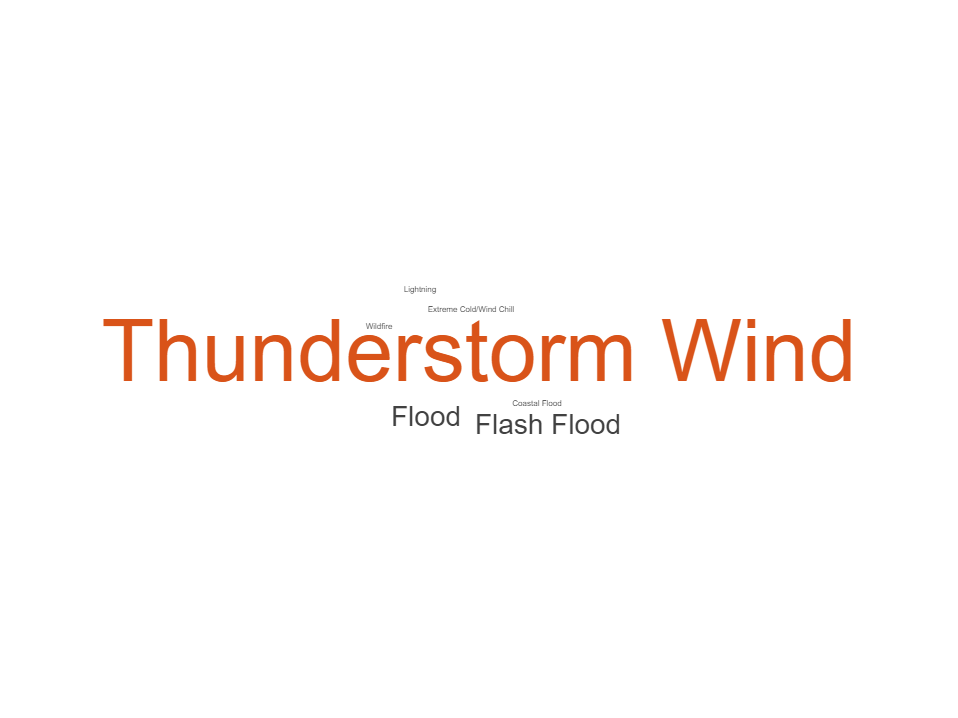

wordcloud(costlyStormEvents.EVENT_TYPE);

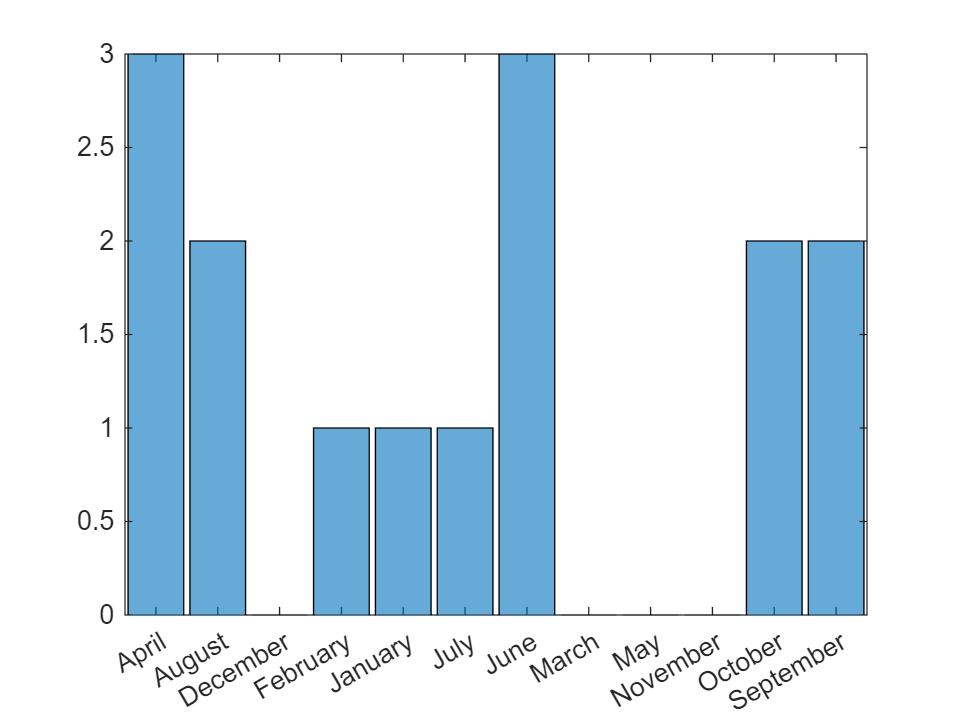

histogram(costlyStormEvents.MONTH_NAME);

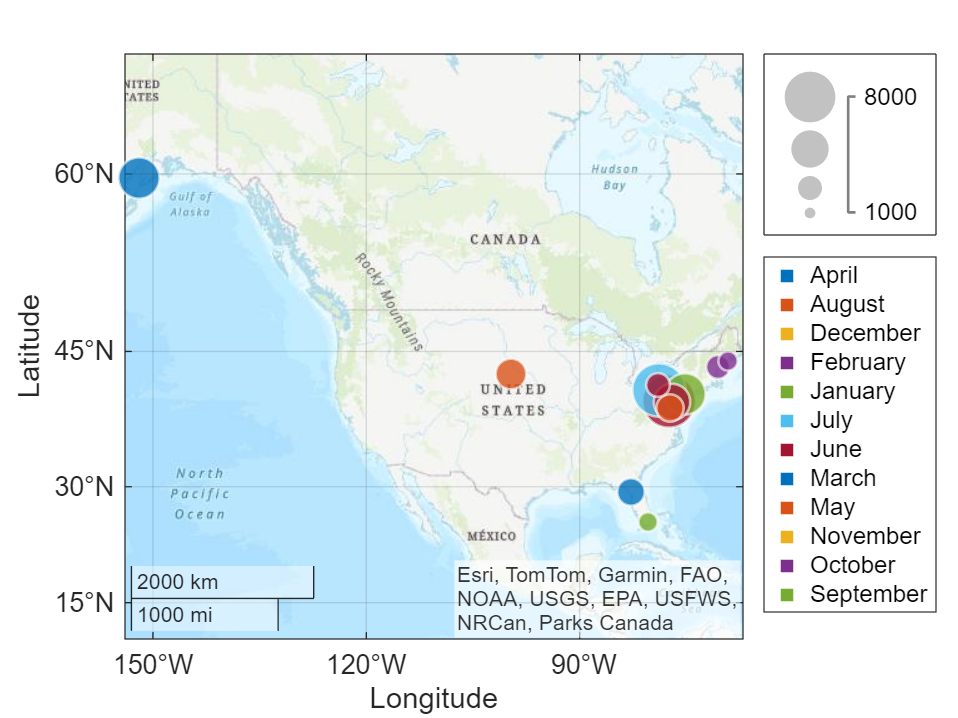

gb3 = geobubble(costlyStormEvents.BEGIN_LAT,costlyStormEvents.BEGIN_LON,costlyStormEvents.DAMAGE_PROPERTY,costlyStormEvents.MONTH_NAME,"Basemap","topographic");

## **5)** Implement Analysis of Data 

**Could Machine Learning algorithms be used to develop a predictive model from this example dataset?**

[https://www.mathworks.com/products/statistics.html](https://www.mathworks.com/products/statistics.html)

[https://www.mathworks.com/help/stats/classificationlearner-app.html](https://www.mathworks.com/help/stats/classificationlearner-app.html)

load trainedModel.mat

**Checking our model with 2024 data**

data2train = importxlsx("data2021.xlsx");
data2check = importxlsx("data2024.xlsx");

[dataTrained,acc] = trainClassifier(data2check)

dataTrained = struct with fields:
            predictFcn: @(x)treePredictFcn(predictorExtractionFcn(x))
     RequiredVariables: {'STATE'  'MONTH_NAME'  'BEGIN_LAT'  'BEGIN_LON'  'END_LAT'  'END_LON'}
    ClassificationTree: [1×1 ClassificationTree]
                 About: 'This struct is a trained model exported from Classification Learner R2023b.'
          HowToPredict: 'To make predictions on a new table, T, use: ↵  [yfit,scores] = c.predictFcn(T) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵The table, T, must contain the variables returned by: ↵  c.RequiredVariables ↵Variable formats (e.g. matrix/vector, datatype) must match the original training data. ↵Additional variables are ignored. ↵ ↵For more information, see How to predict using an exported model.'


acc = 0.6911

A= dataTrained.ClassificationTree.X;
B= dataTrained.ClassificationTree.Y;

### Check our model

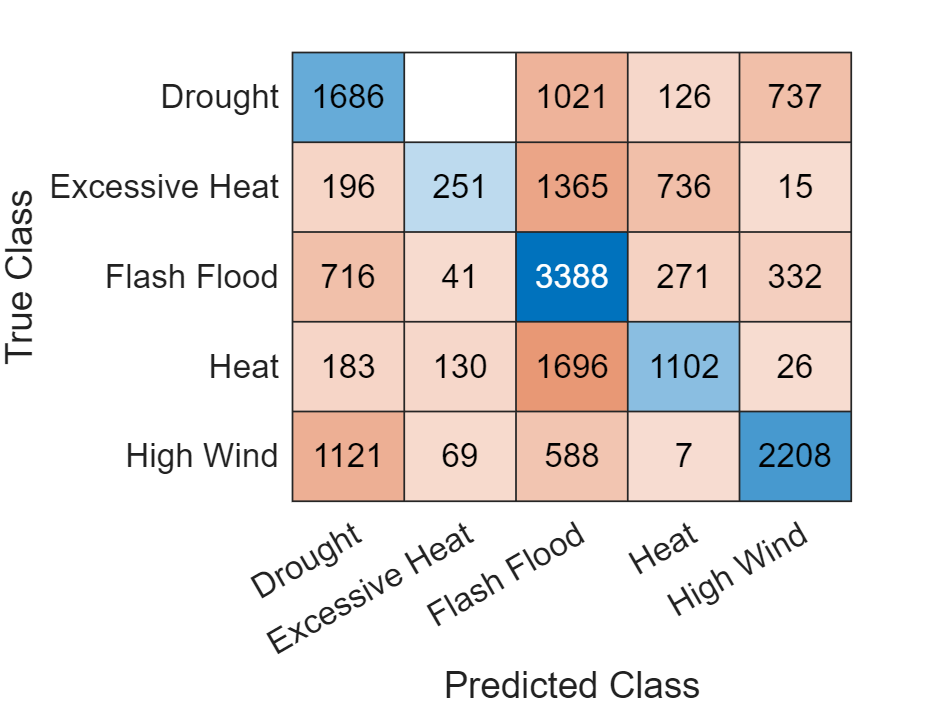

[yfit,scores] = trainedModel.predictFcn(data2check);
confusionchart(data2check.EVENT_TYPE,yfit)

fprintf("El porcentaje de precisión del modelo corresponde al %.2f%%\n", acc*100);

El porcentaje de precisión del modelo corresponde al 69.11%


## 6) View a Report of the Analysis 

[https://www.mathworks.com/help/matlab/live-scripts-and-functions.html](https://www.mathworks.com/help/matlab/live-scripts-and-functions.html)

[https://www.mathworks.com/help/matlab/matlab_prog/share-live-scripts.html](https://www.mathworks.com/help/matlab/matlab_prog/share-live-scripts.html)